clear
filename = sort(split(ls("storage")));
filename = filename{end-8};
binDataFile = fopen("storage/"+filename,"r");

# Estudiar storage_20250226_002449

nElem = fread(binDataFile,1,"uint32");
for i=[1:1000]
    header_elem = strsplit(fscanf(binDataFile,"%10s",1), "\0");
    header_elem = header_elem{1};
    if all(header_elem == char(255))
        break 
    end
    header(i) = string(header_elem);
end

%header = readtable("storage/layout.csv");


fseek(binDataFile, 0x1000,"bof");

data = fread(binDataFile,width(header)*nElem,"float32");
data = array2table(reshape(data,width(header),[])');
data.Properties.VariableNames = header;

mag_norm = mean(sqrt(data.mag_x.^2 + data.mag_y.^2 + data.mag_z.^2));
data.mag_x = data.mag_x ./ mag_norm;
data.mag_y = data.mag_y ./ mag_norm;
data.mag_z = data.mag_z ./ mag_norm;

timedata = table2timetable(data(:,2:end),"RowTimes",seconds(data.time_s));
fclose(binDataFile);

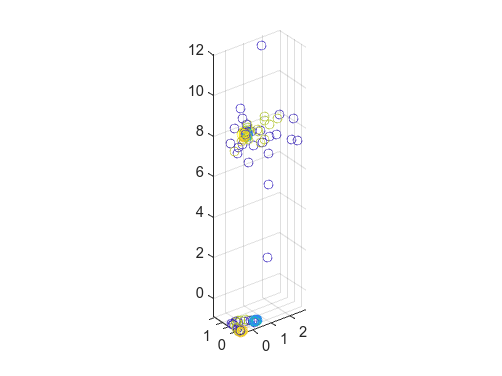

figure
scatter3(data.mag_x ,data.mag_y, data.mag_z,'CData',data.time_s)
hold on
scatter3(data.acc_x,data.acc_y, data.acc_z, 'CData',data.time_s)
axis equal

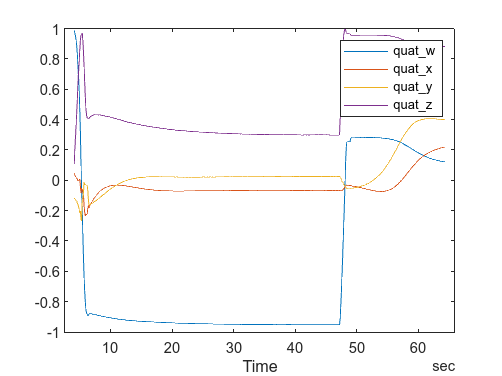

figure
plot(timedata, "Time",["quat_w", "quat_x", "quat_y", "quat_z"]);
legend

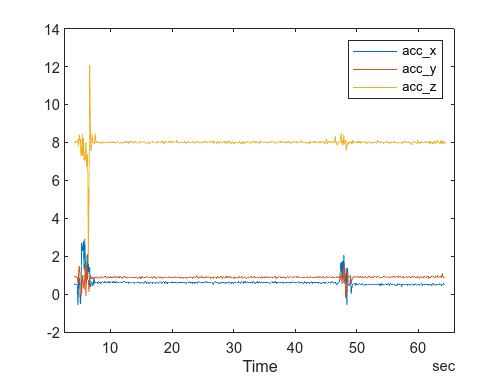

figure
plot(timedata, "Time", ["acc_x","acc_y","acc_z"]);
legend

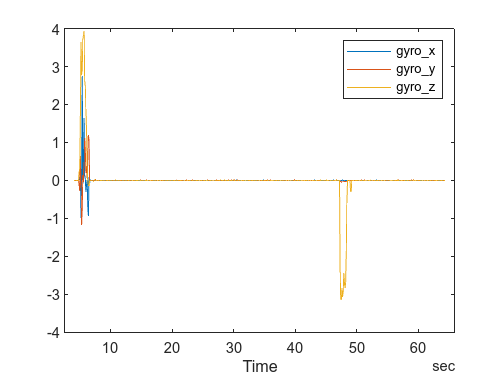

figure
plot(timedata, "Time", ["gyro_x", "gyro_y", "gyro_z"]);
legend

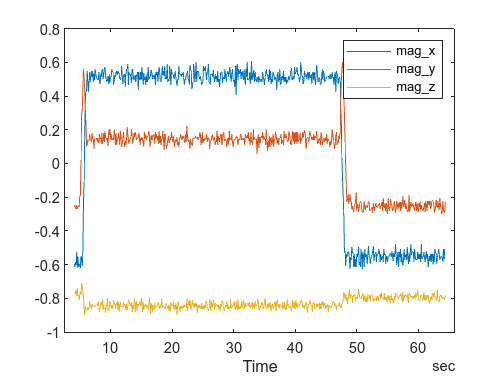

figure

plot(timedata, ["mag_x","mag_y", "mag_z"]);
legend

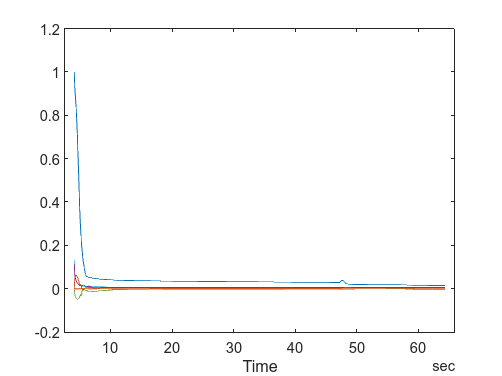

P = data(:,15:30);
figure
plot(timedata, "Time", ["P11", "P12", "P13", "P14", "P21", "P22", "P23", "P24", "P31", "P32", "P33", "P34", "P41", "P42", "P43", "P44"]);

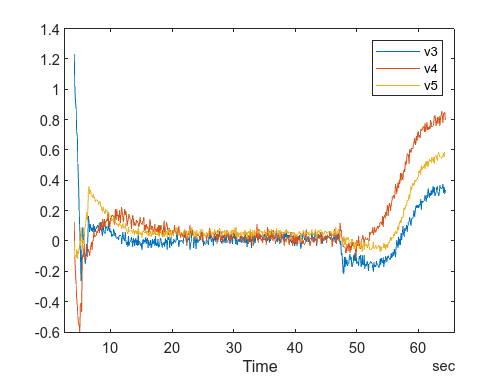

figure
plot(timedata, "Time", ["v3","v4","v5"])
legend

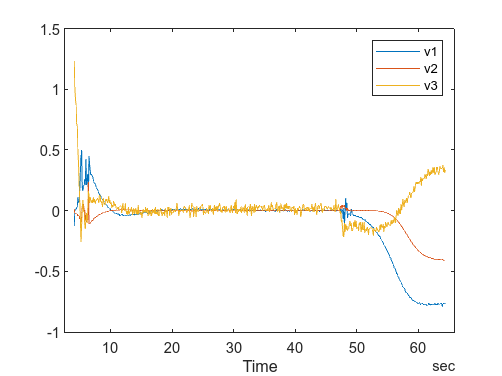

figure
plot(timedata, "Time", ["v1","v2","v3"])
legend

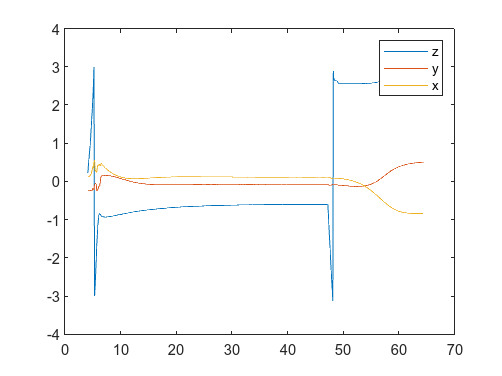

quats = quaternion(table2array(data(:,["quat_w","quat_x","quat_y","quat_z"])));
euls = quats.euler("ZYX","point");
figure
plot(data.time_s,euls(:,1));
hold on
plot(data.time_s,euls(:,2));
plot(data.time_s,euls(:,3));
legend("z","y","x");


% Create an Aero.Animation object
hAnim = Aero.Animation;

% Create the aircraft body using a geometry file (e.g., an AC3D file).
% Replace 'yourAircraft.ac' with your aircraft model file.
hAnim.createBody('pa24-250_orange.ac','Ac3d');

% Extract quaternion data and convert to Euler angles.
% MATLAB’s quat2eul returns [yaw, pitch, roll] (in radians) for a quaternion [w x y z].
quatData = timedata{:, {'quat_w','quat_x','quat_y','quat_z'}};
eul = quaternion(quatData).euler("ZYX","point");  % [yaw, pitch, roll] in radians

% Create a 6DoF matrix. Here, we assume no position change so we set [x y z] to zeros.
% Rearrange Euler angles to [roll, pitch, yaw] as required.
numSamples = height(timedata);
data6DoF = [seconds(timedata.Time), zeros(numSamples,3), eul(:,3), eul(:,2), eul(:,1)];

% Assign the data to the animation object:
hAnim.Bodies{1}.TimeSeriesSourceType = 'Array6DoF';
hAnim.Bodies{1}.TimeSeriesSource = data6DoF;


% (Optional) Adjust camera settings if desired.
hAnim.Camera.PositionFcn = @staticCameraPosition;
hAnim.Figure.Position(1) = hAnim.Figure.Position(1) + 572/2;

% Initialize the animation at the start time
startTime = timedata.Time(1);
hAnim.updateBodies(seconds(startTime));
hAnim.updateCamera(seconds(startTime));
hAnim.show();

figure(hAnim.Figure)
txt = text(-3,-3,string(timedata.Time(1)))

txt =   Text (4.1154 sec) with properties:

                 String: '4.1154 sec'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [-3 -3 0]
                  Units: 'data'

  Show all properties


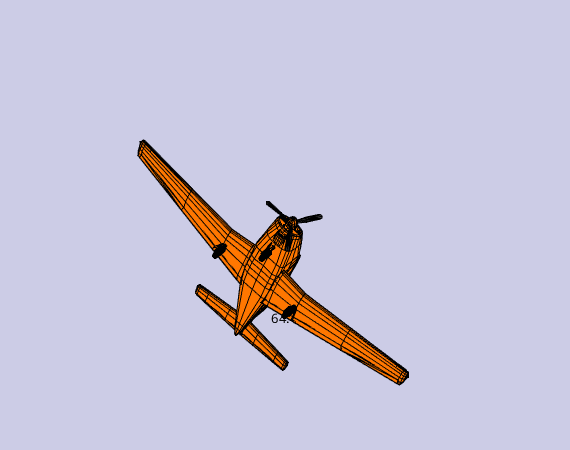

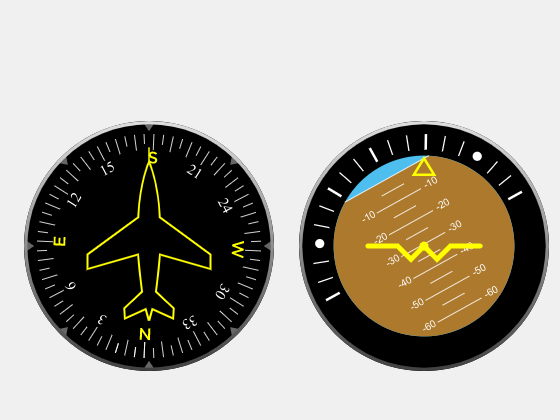


f = uifigure;
heading = uiaeroheading(f);
horizon = uiaerohorizon(f);
heading.Position = [25 50 250 250];
horizon.Position = [300 50 250 250];

% Animate through the data
for k = 1:length(timedata.Time)
    currentTime = seconds(timedata.Time(k));
    hAnim.updateBodies(currentTime);
    %hAnim.updateCamera(currentTime);
    txt.String = string(timedata.Time(k));
    heading.Value = euls(k,1)*180/pi;
    horizon.Value =  euls(k,2:3)*180/pi;
    drawnow;  % refresh the figure
    pause(0.005);  % adjust pause for desired speed
end

% [A,b] = magcal(data(8:10,1:400)')
% Afile = fopen("calibration/A_mag_cal.bin","w");
% fwrite(Afile,A,"float32");
% bfile = fopen("calibration/b_mag_cal.bin","w");
% fwrite(bfile,b,"float32");
% 
% fclose(Afile);
% fclose(bfile);